## Load and import dataset

clear all; 
load('../2018/data/dc_corr.mat','dc'); 
addpath('../2018/functions/'); load('coastlines.mat'); warning('off')
load('../2018/data/BelowRadarMPS.mat');

## Convert the data to a simple structure

Define the `data` structure with all data.

data.name = {dc.name}';
data.lat = [dc.lat]';
data.lon = [dc.lon]';
data.height = [dc.height]';
data.heightDEM = [dc.heightDEM]';
data.maxrange = [dc.maxrange]';
data.nrad = numel(data.name);
data.time = dc(1).time';
data.alt = dc(1).alt';
data.NNT = datenum(repmat(data.time,1,numel(dc))-mean(cat(3,[dc.dawn],[dc.dusk]),3)) ./ datenum([dc.dawn]-[dc.dusk])*2;

Initiate empty density matrix

data_denss_sim = nan(numel(data.time),  numel(dc), size(MPS{1},3));

Loop for eac radar

for i_d=1:numel(dc)
    % Vertical agregation accounts for the DEM based on VolBelow.
    % First, find the direction of flight of the lowest non-nan bin
    [~, id]  = max(~isnan(dc(i_d).dd), [], 2);
    dir_lowest = dc(i_d).dd(sub2ind(size(dc(i_d).dd), (1:numel(data.time))',id));
    % Transform this direction angle (0-360°) into the index of alpha (-90°-90°)
    dir_lowest_round = round(dir_lowest,-1);
    id_alpha=nan(size(dir_lowest_round));
    id_alpha(dir_lowest_round>=0 & dir_lowest_round<90) = dir_lowest_round(dir_lowest_round>=0 & dir_lowest_round<90)+90;
    id_alpha(dir_lowest_round>=90 & dir_lowest_round<270) = dir_lowest_round(dir_lowest_round>=90 & dir_lowest_round<270)-90;
    id_alpha(dir_lowest_round>=270 & dir_lowest_round<360) = dir_lowest_round(dir_lowest_round>=270 & dir_lowest_round<360)-270;
    id_alpha = id_alpha/10+1;
    height_vol = nan(numel(data.time),numel(data.alt));
    height_vol(~isnan(id_alpha),:) = dc(i_d).VolBelow(id_alpha(~isnan(id_alpha)),:);
    
    % Integrate volume density into surface density based on the direction and corresponding volume. bird/km^2
    % data.denss(:,i_d) = sum(data_dens(:,:,i_d) .* height_vol,2);
    
    % Computing with result of MPS
    tmp = dc(i_d).dens4;
    data_denss_MPS = nan(size(tmp,1),size(MPS{i_d},3),size(tmp,2));
    for i_real=1:size(MPS{i_d},3)
        tmp(:,1:dc(i_d).scatter_lim-1) = MPS{i_d}(:,1:dc(i_d).scatter_lim-1,i_real);
        data_denss_MPS(:,i_real,:) = tmp .* height_vol;
    end
    data_denss_sim(:,i_d,:) = sum(data_denss_MPS,3);
    
    % Compute speed
    nb_bird = permute(nanmean(data_denss_MPS,2),[1 3 2]);
    w_MTR = nb_bird ./ repmat(nansum(nb_bird,2),1,size(nb_bird,2));
    
    data.vs(:,i_d) = nansum(w_MTR .* dc(i_d).v2,2);
    data.us(:,i_d) = nansum(w_MTR .* dc(i_d).u2,2);
    
    % if data present initially
    data.isdata(:,i_d)=~all(isnan(dc(i_d).DBZH),2);
end
data.vs(data.vs==0)=nan;
data.us(data.us==0)=nan;

Set  data during the day to zero

data_denss_sim(repmat((data.NNT<-1 | data.NNT>1),1,1,size(data_denss_sim,3)))=nan;
data.vs(data.NNT<-1 | data.NNT>1)=nan;
data.us(data.NNT<-1 | data.NNT>1)=nan;

Remove 0 value because of the transformation

data_denss_sim(data_denss_sim==0)=nan;

Remove data when there is only a few data point (8 => 2h00) per day

tmp=dateshift(data.time,'start','day','nearest');
day_id=findgroups(datenum(tmp));
G = findgroups(day_id);
nb = splitapply(@nansum,~isnan(data_denss_sim),G);
data_denss_sim(nb(day_id,:,:)<8)=nan;

Remove time with all day or no data to save space

data.id_t=all(all(isnan(data_denss_sim),2),3);
data.time(data.id_t)=[];
data.ntime = numel(data.time);
data.NNT(data.id_t,:)=[];
data_denss_sim(data.id_t,:,:)=[];
data.vs(data.id_t,:)=[];
data.us(data.id_t,:)=[];
data.isdata(data.id_t,:)=[];
tmp=dateshift(data.time,'start','day','nearest');
[data.day_id,data.day]=findgroups(datenum(tmp));
G = findgroups(data.day_id);
nb = splitapply(@nansum,~isnan(data_denss_sim),G);

Clear variable to make space (if necessary)

clear id_t tmp1 dens_lim tmp w_MTR nb_bird data_u data_v ff dd data_dens dir_lowest dir_lowest_round height_vol id_alpha id i_d dir i_real data_denss_MPS MPS

id_sp = data.time>datetime('1-Mar-2018') & data.time<datetime('1-May-2018');
id_esp = data.time>datetime('1-Mar-2018') & data.time<datetime('1-April-2018');
id_lsp = data.time>datetime('1-April-2018') & data.time<datetime('1-May-2018');
id_au = data.time>datetime('1-August-2018') & data.time<datetime('1-Nov-2018');
id_eau = data.time>datetime('1-August-2018') & data.time<datetime('1-Oct-2018');
id_lau = data.time>datetime('1-Oct-2018') & data.time<datetime('1-Nov-2018');
id_de = [false; true(15,1); false(21,1)]; %repmat(permute(id_de,[3,2,1]),size(v_g,1),size(v_g,2),1);
id_fr = [false(16,1); true(19,1); false(2,1)]; %repmat(permute(id_fr,[3,2,1]),size(v_g,1),size(v_g,2),1);
id_s = [id_esp id_lsp id_eau id_lau];
id_y = [id_sp id_au];

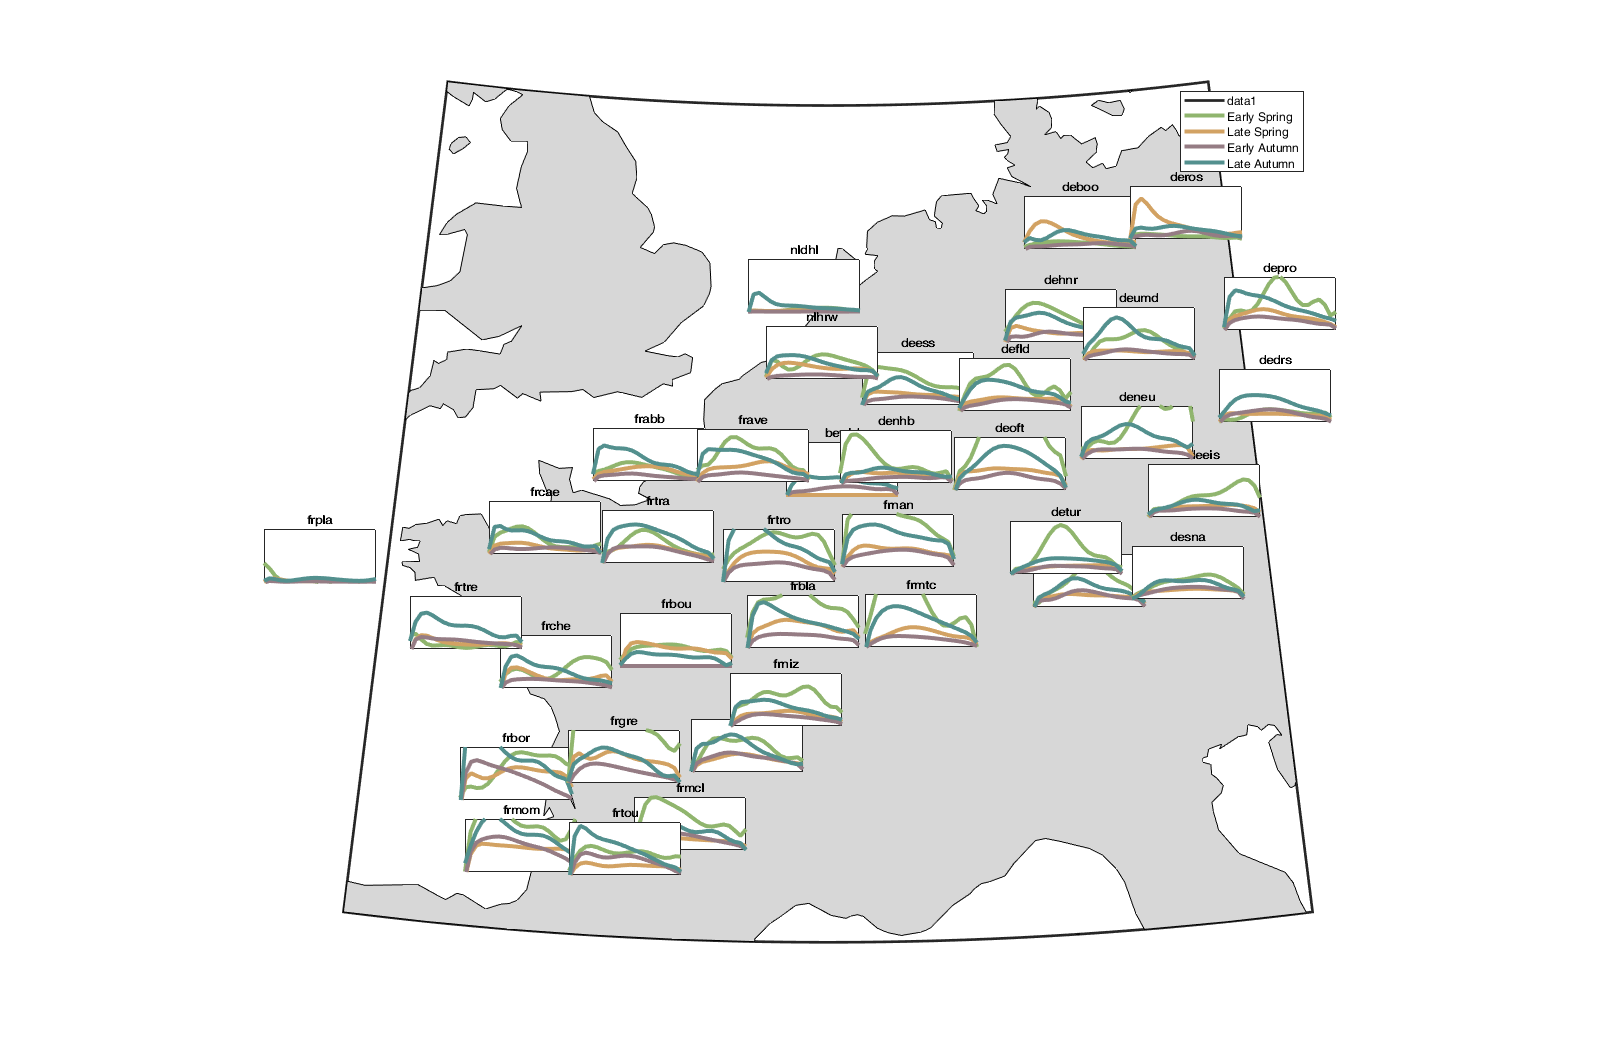

MTR = mean(data_denss_sim,3) .* sqrt( data.vs.^2 + data.us.^2 );
col = [[81 161 114];[206 202 105];[213 122 93];[85 126 170]]/255;
col2 = [mean(col(1:2,:)); mean(col(2:3,:)); mean(col(3:4,:)); mean([col(1,:);col(4,:)])];

figure('position',[0 0 1600 1600]); hold on; 
h=worldmap([floor(min(data.lat)) ceil(max(data.lat))], [floor(min(data.lon)) ceil(max(data.lon))]);
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
geoshow('landareas.shp', 'FaceColor', [215 215 215]./255);
%plotm(coastlat, coastlon,'k'); geoshow('worldrivers.shp','Color', 'blue')
scatterm([dc.lon],[dc.lat],'filled','k');

w=.07; h=0.05; m =.2; 
pw = @(lon) (lon-min([dc.lon]))/(max([dc.lon])-min([dc.lon]))*(1-2*m)+m;
ph = @(lat) (lat-min([dc.lat]))/(max([dc.lat])-min([dc.lat]))*(1-2*m)+m;

plotm([1 1],[1 1],'LineWidth',3,'Color',col2(1,:),'DisplayName','Early Spring')
plotm([1 1],[1 1],'LineWidth',3,'Color',col2(2,:),'DisplayName','Late Spring')
plotm([1 1],[1 1],'LineWidth',3,'Color',col2(3,:),'DisplayName','Early Autumn')
plotm([1 1],[1 1],'LineWidth',3,'Color',col2(4,:),'DisplayName','Late Autumn')
legend()

for i_d=1:numel(dc)
    subAX = axes('position',[pw(dc(i_d).lon)-w/2 ph(dc(i_d).lat)-h/2 w h]);
    hold on;
    for i_s=1:size(id_s,2)
        % subplot(6,7,i_d); hold on;
        id = ~isnan(data.NNT(:,i_d)) & ~isnan(MTR(:,i_d)) & id_s(:,i_s);
        x=data.NNT(id,i_d); y=MTR(id,i_d);
        %scatter(x, y, [],col(i_s,:),'.');
        [p,S] = polyfit(x,y,8);
        [yhat,yuc] = polyval(p,-1:0.1:1,S);
        plot(-1:0.1:1,yhat,'-','LineWidth',3, 'Color',col2(i_s,:));
        %plot(-1:0.1:1,yhat+yuc/3,'--','LineWidth',1, 'Color',col2(i_s,:));
        %plot(-1:0.1:1,yhat-yuc/3,'--','LineWidth',1, 'Color',col2(i_s,:));
        ylim([0 500])
        title(dc(i_d).name); box on; set(subAX,'XTick',[],'YTick',[]);
    end
end

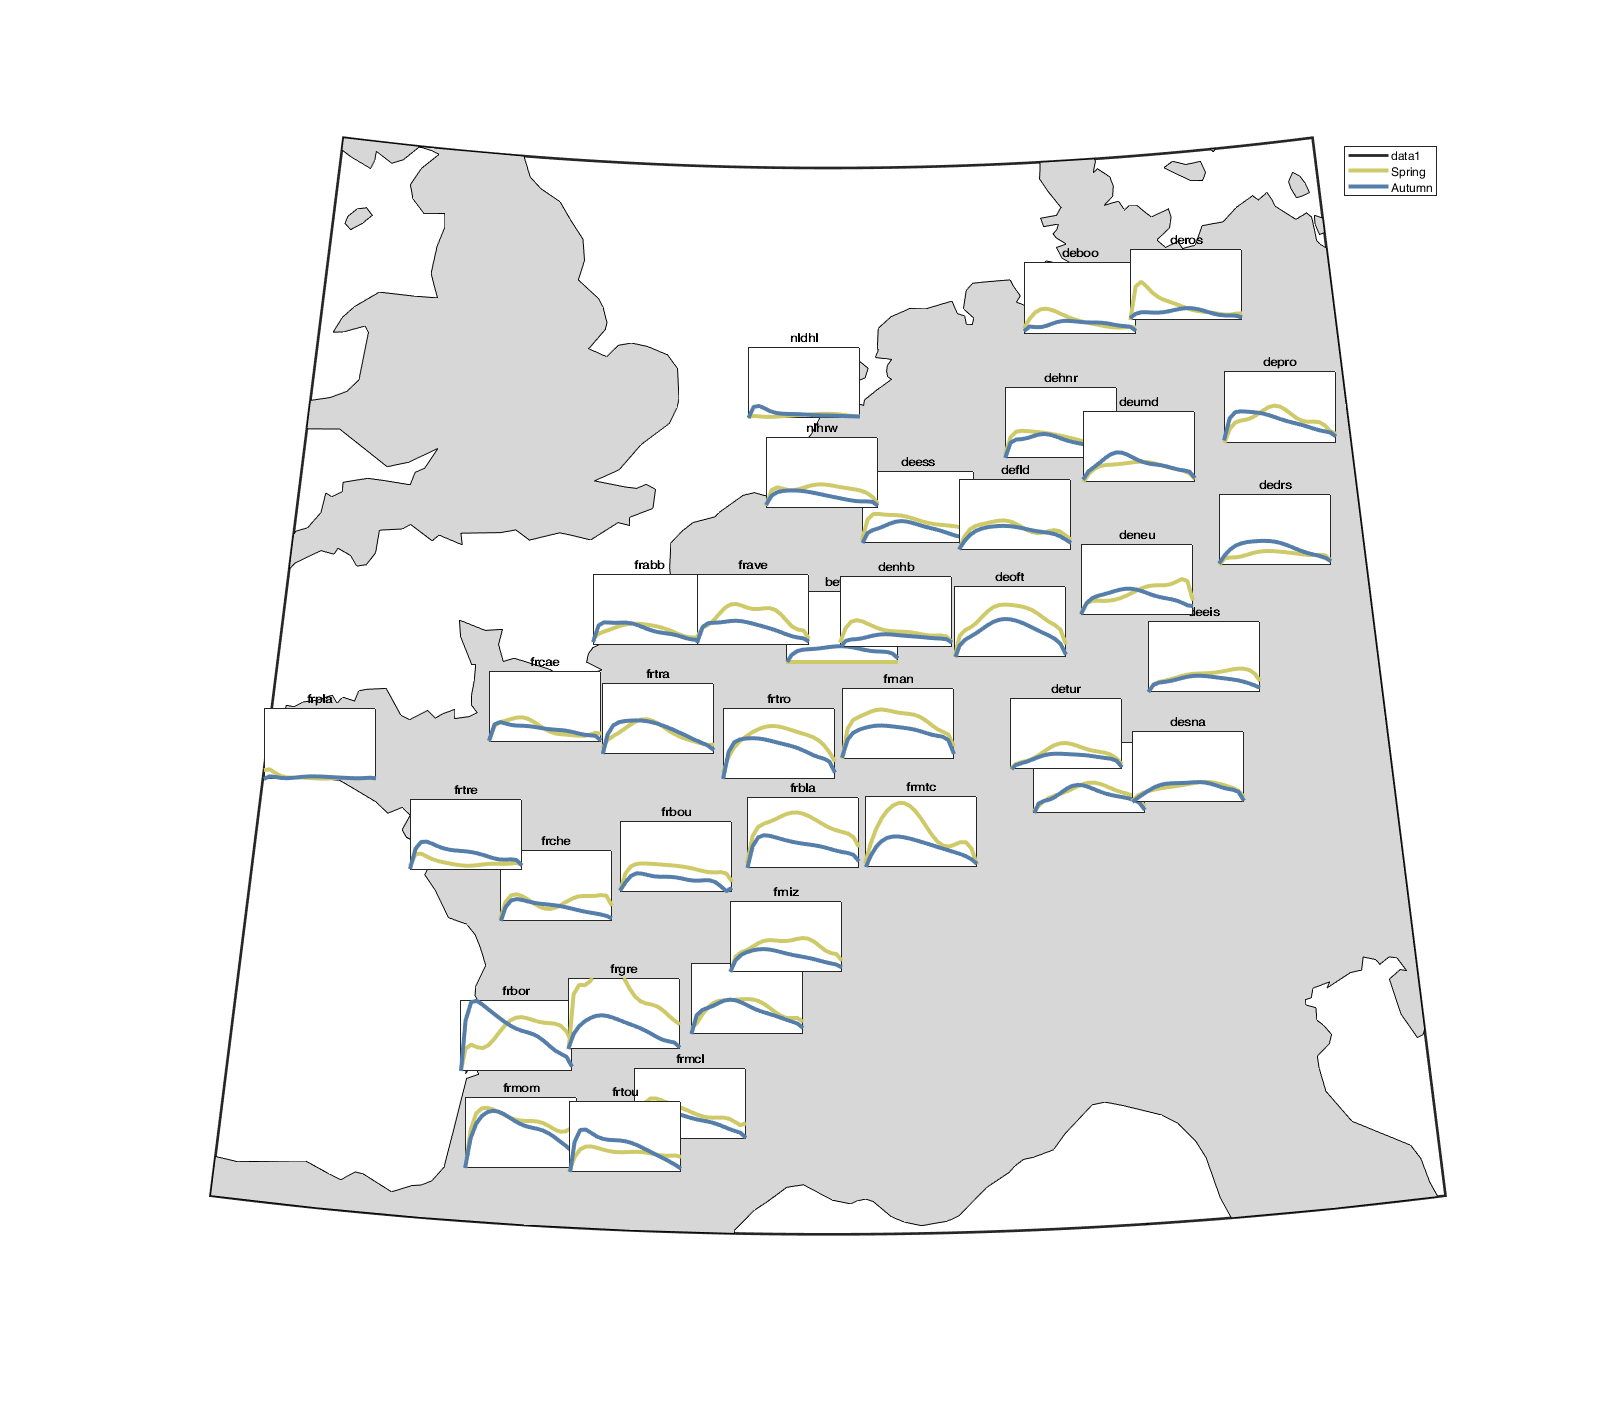

MTR = mean(data_denss_sim,3) .* sqrt( data.vs.^2 + data.us.^2 );
col = [[81 161 114];[206 202 105];[213 122 93];[85 126 170]]/255;

figure('position',[0 0 1600 1600]); hold on; 
h=worldmap([floor(min(data.lat)) ceil(max(data.lat))], [floor(min(data.lon)) ceil(max(data.lon))]);
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
geoshow('landareas.shp', 'FaceColor', [215 215 215]./255);
%plotm(coastlat, coastlon,'k'); geoshow('worldrivers.shp','Color', 'blue')
scatterm([dc.lon],[dc.lat],'filled','k');

w=.07; h=0.05; m =.2; 
pw = @(lon) (lon-min([dc.lon]))/(max([dc.lon])-min([dc.lon]))*(1-2*m)+m;
ph = @(lat) (lat-min([dc.lat]))/(max([dc.lat])-min([dc.lat]))*(1-2*m)+m;

plotm([1 1],[1 1],'LineWidth',3,'Color',col(2,:),'DisplayName','Spring')
plotm([1 1],[1 1],'LineWidth',3,'Color',col(4,:),'DisplayName','Autumn')
legend()
for i_d=1:numel(dc)
    subAX = axes('position',[pw(dc(i_d).lon)-w/2 ph(dc(i_d).lat)-h/2 w h]);
    hold on;
    for i_s=1:size(id_y,2)
        % subplot(6,7,i_d); hold on;
        id = ~isnan(data.NNT(:,i_d)) & ~isnan(MTR(:,i_d)) & id_y(:,i_s);
        x=data.NNT(id,i_d); y=MTR(id,i_d);
        %scatter(x, y, [],col(i_s,:),'.');
        [p,S] = polyfit(x,y,8);
        [yhat,yuc] = polyval(p,-1:0.1:1,S);
        plot(-1:0.1:1,yhat,'-','LineWidth',3, 'Color',col(i_s*2,:));
        %plot(-1:0.1:1,yhat+yuc/3,'--','LineWidth',1, 'Color',col2(i_s,:));
        %plot(-1:0.1:1,yhat-yuc/3,'--','LineWidth',1, 'Color',col2(i_s,:));
        ylim([0 500])
        title(dc(i_d).name); box on; set(subAX,'XTick',[],'YTick',[]);
    end
end

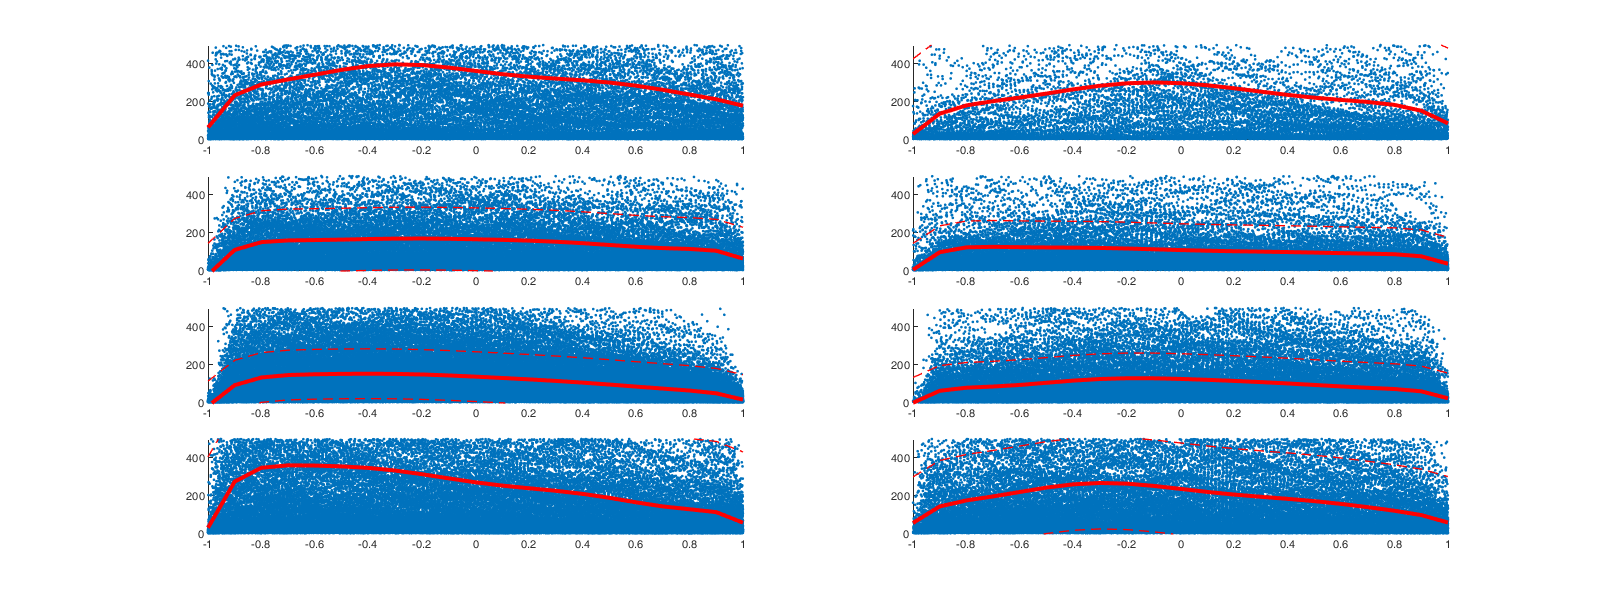

figure('position',[0 0 1600 600]); 
for i_s=1:size(id_s,2)
        subplot(4,2,(i_s-1)*2+1); hold on;
        id = repmat(id_fr',37846,1) & ~isnan(data.NNT) & ~isnan(MTR) & repmat(id_s(:,i_s),1,numel(dc)) & MTR>5;
        x=data.NNT(id); y=MTR(id);
        scatter(x, y, '.');
        [p,S] = polyfit(x,y,8);
        [yhat,yuc] = polyval(p,-1:0.1:1,S);
        plot(-1:0.1:1,yhat,'-r','LineWidth',3);
        plot(-1:0.1:1,yhat+yuc,'--r','LineWidth',1);
        plot(-1:0.1:1,yhat-yuc,'--r','LineWidth',1);
        ylim([0 500])
        
        subplot(4,2,(i_s-1)*2+2); hold on;
        id = repmat(id_de',37846,1) & ~isnan(data.NNT) & ~isnan(MTR) & repmat(id_s(:,i_s),1,numel(dc)) & MTR>5;
        x=data.NNT(id); y=MTR(id);
        scatter(x, y, '.');
        [p,S] = polyfit(x,y,8);
        [yhat,yuc] = polyval(p,-1:0.1:1,S);
        plot(-1:0.1:1,yhat,'-r','LineWidth',3);
        plot(-1:0.1:1,yhat+yuc,'--r','LineWidth',1);
        plot(-1:0.1:1,yhat-yuc,'--r','LineWidth',1);
        ylim([0 500])
end

Parametrize the curve of each night. Explains this/these parameters a a function of

- time of year / long-short distant migrant

- temperature/wind 

- distance to coast

- altitude of radar / terrain

- barrier on the way? 

Data selection:

- data available during the entire night.

- no rain?

- minimum mtr? avoid low migration contamination

- normalized the mtr to get only (unscale) nightly pattern ?

Parametrization of the curve

- polynomial/wavelet -> ML predictor? (tree-based?)

- gam?

- more simple: (1) first half/second half of night, (2) slope during the first hour, (3) peack MTR, (4) 1 or two peak ...